**An Introduction to Robotics, By Prof. Hamid D. Taghirad & Mohammad A. Khosravi Copyright ARAS @2023**

#  This code provides the isotropic analysis of a 2R manipulator.

## Parameter Definitions

clear; % Clear workspace
clc; % Clear command window

syms x th2 real % Symbolic variables for position and joint angle
a1 = sqrt(2); % Link length of the first joint
a2 = 1; % Link length of the second joint
k = 10^3; % Stiffness constant

Jacobian analysis: symbolic

Problem 4.13 in the book

J = [a1 * sin(th2), 0; a1 * cos(th2) + a2, a2]; % Jacobian matrix in symbolic form
JJ = simplify(J * J');
p = x * eye(2, 2) - JJ; % Characteristic equation
D = simplify(det(p)); % Determinant of the characteristic equation
lambda = simplify(solve(D == 0, x)); % Eigenvalues of the Jacobian matrix

Jacobian analysis: numeric

Problem 4.14 in the book

J1 = [sqrt(2), 0; 1, 1];
JJ1 = J1 * J1';
[U, S, V] = svd(J1); % Singular value decomposition of Jacobian
[v1, e1] = eig(JJ1); % Eigenvalues of JJ'


Stiffness analysis: numeric

C = J1 * J1' / k; % Stiffness matrix
[U, S, V] = svd(C); % Singular value decomposition of stiffness matrix
[v, e] = eig(C' * C); % Eigenvalues of the stiffness matrix


Problem 4.15 in the book

th2 = 0:0.01:pi;
alpha = [0.707; 1; 1.2; 1.8];
kappa = zeros(length(th2), 4);
for i = 1:4
    kappa(:, i) = 2 * sin(th2) ./ (1 / alpha(i) + 2 * alpha(i) + 2 * cos(th2));
end


Figure 4.26 in the book

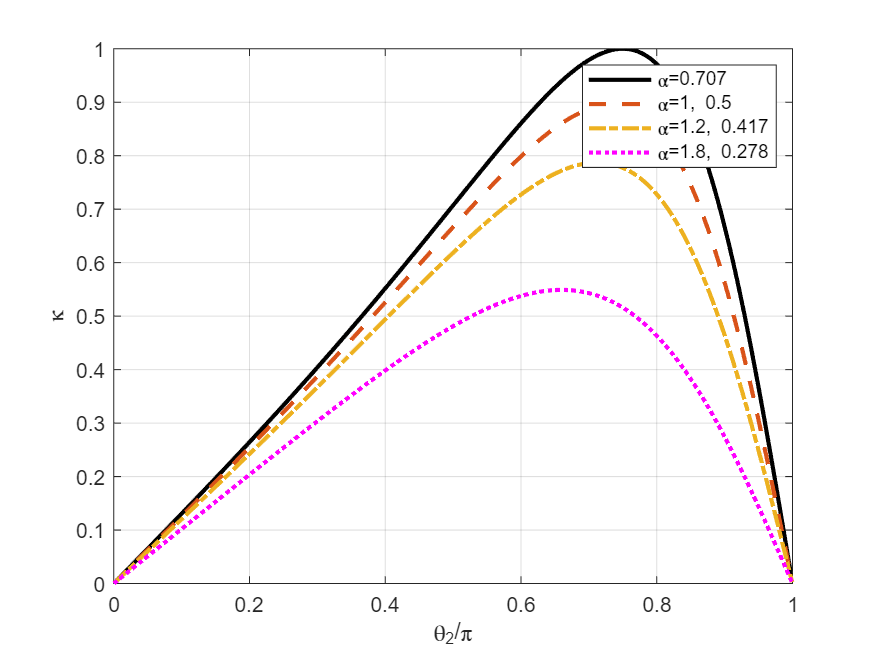

plot(th2/pi, kappa(:, 1), '-k', th2/pi, kappa(:, 2), '--', ...
     th2/pi, kappa(:, 3), '-.', th2/pi, kappa(:, 4), 'm:')
set(findall(figure(1), 'type', 'line'), 'linewidth', 2)
grid on
legend('\alpha=0.707', '\alpha=1, 0.5', '\alpha=1.2, 0.417', '\alpha=1.8, 0.278')
xlabel('\theta_2/\pi')
ylabel('\kappa')